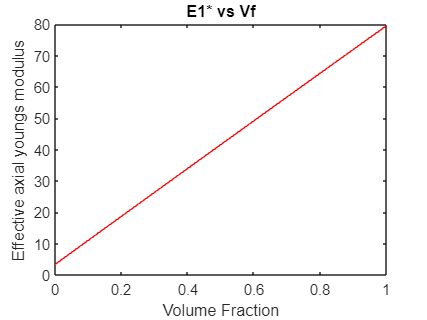

% CCA
clear all;
format long e
syms Vf
t = linspace(0,1,100);
% Volume fraction
   % Vf = 0.5;
   Vm = 1.0 - Vf;
% stiffness matrix of fibre
% Fibre is transversely isotropic with following properties in GPa
  E1 = 80;
  E2 = 80;
  E3 = E2;
  G12 = 33.33;
  G13 = 33.33;
  G23 = 33.33;
  nu_12 = 0.2;
  nu_13 = nu_12; 
  nu_23 = E2/(2.0 * G23) - 1.0;
  nu_21 = nu_12 * E2/E1;
  nu_31 = nu_13 * E3/E1;
  nu_32 = nu_23 * E3/E2;

% Initialization
  s = zeros(6,6);
  Cf = zeros(6,6);
  Cm = zeros(6,6);
%  
    s(1,1)=1.0/E1;
    s(2,2)=1.0/E2;
    s(3,3)=1.0/E3;   
    s(1,2)=-nu_21/E2;
    s(1,3)=-nu_31/E3;  
    s(2,1)=-nu_21/E2;
    s(2,3)=-nu_32/E3;  
    s(3,1)=-nu_13/E1; 
    s(3,2)=-nu_23/E2;
% Following order is according order in Abaqus
    s(4,4)=1.0/G12;
    s(5,5)=1.0/G13;
    s(6,6)=1.0/G23;
    Cf = inv(s);
% Calculate the stiffness matrix of matrix
% Matrix is isotropic with following properties
  E0 = 3.35;
  XNU = 0.35;
%  
     XX = E0 * (1.0 - XNU)/((1.0 - 2.0 * XNU)*(1.0 + XNU));
     YY = E0 * XNU/((1.0 - 2.0 * XNU)*(1.0 + XNU));
     ZZ = E0 /(2.0 * (1.0 + XNU));
%
            for I = 1:3
               for J = 1:3
                  Cm(I,J) = YY;
               end
               Cm(I,I) = XX;
               Cm(I+3,I+3) = ZZ;
            end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%            
% Effective stiffness matrix
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
a = sqrt(Vf);
b = 1;

Af = ((a^2)*(Cm(1,1)-Cm(1,2))*(Cf(1,2)+Cm(1,2))+(b^2)*(Cm(1,2)*(Cf(1,2)-Cm(1,2))+Cm(1,1)*(Cf(1,2)+Cm(1,2))))/((a^2)*(Cm(1,1)-Cm(1,2))*(Cm(1,1)+Cm(1,2)-Cf(2,2)-Cf(2,3))-(b^2)*(Cm(1,1)+Cm(1,2))*(Cm(1,1)-Cm(1,2)+Cf(2,2)+Cf(2,3)));

Am = ((a^2)*(Cm(1,1)-Cm(1,2))*(Cf(1,2)-Cm(1,2))+(b^2)*Cm(1,2)*(Cm(1,1)-Cm(1,2)+Cf(2,2)+Cf(2,3)))/((a^2)*(Cm(1,1)-Cm(1,2))*(Cm(1,1)+Cm(1,2)-Cf(2,2)-Cf(2,3))-(b^2)*(Cm(1,1)+Cm(1,2))*(Cm(1,1)-Cm(1,2)+Cf(2,2)+Cf(2,3)));

Bm = ((a^2)*(b^2)*(Cm(1,1)*Cf(1,2)+Cm(1,2)*(Cf(1,2)-Cf(2,2)-Cf(2,3))))/((a^2)*(Cm(1,1)-Cm(1,2))*(Cm(1,1)+Cm(1,2)-Cf(2,2)-Cf(2,3))-(b^2)*(Cm(1,1)+Cm(1,2))*(Cm(1,1)-Cm(1,2)+Cf(2,2)+Cf(2,3)));

P = pi*(a^2)*(Cf(1,1)+2*Cf(1,2)*Af)+pi*((b^2)-(a^2))*(Cm(1,1)+2*Cm(1,2)*Am);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

E1_eff = P/(pi*b^2);
E1_eff = double(subs(E1_eff,Vf,t));
plot(t,E1_eff,'r','Linewidth',0.2);
title("E1* vs Vf")
xlabel("Volume Fraction")
ylabel("Effective axial youngs modulus")

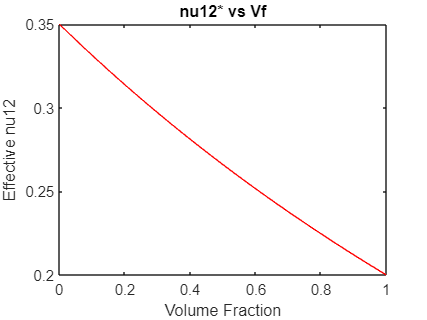


nu12_eff = -(Am + Bm/b^2);
nu12_eff = double(subs(nu12_eff,Vf,t));
plot(t,nu12_eff,'r','Linewidth',0.2);
title("nu12* vs Vf")
xlabel("Volume Fraction")
ylabel("Effective nu12")

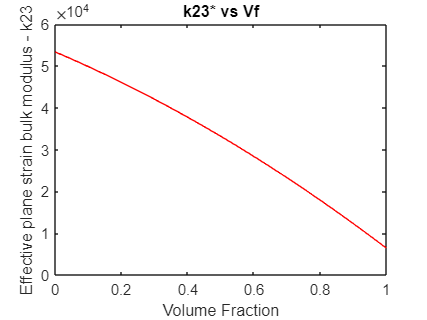


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Effective plane strain bulk modulus k23
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

k23_eff = (-a^2* (Cm(1,1)- Cm(1,2)) * (Cm(1,1) + Cm(1,2) - Cf(2,2) - Cf(2,3)) + b^2 * (Cm(1,1) + Cm(1,2)) * (Cm(1,1) - Cm(1,2) + Cf(2,2) + Cf(2,3))) / 2* (a^2* (Cm(1,1) + Cm(1,2) - Cf(2,2) - Cf(2,3)) + b^2 * (Cm(1,1) - Cm(1,2) + Cf(2,2) + Cf(2,3)));
k23_eff = double(subs(k23_eff,Vf,t));
plot(t,k23_eff,'r','Linewidth',0.2);
title("k23* vs Vf")
xlabel("Volume Fraction")
ylabel("Effective plane strain bulk modulus - k23")

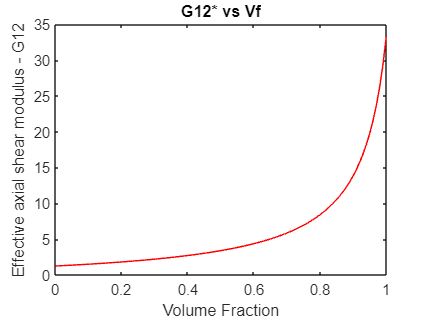


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Effective axial shear modulus
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Gm = Cm(4,4);

G12_eff = Gm*(G12*(1+Vf)+Gm*(1-Vf))/(G12*(1-Vf)+Gm*(1+Vf));
G12_eff = double(subs(G12_eff,Vf,t));
plot(t,G12_eff,'r','Linewidth',0.2);
title("G12* vs Vf")
xlabel("Volume Fraction")
ylabel("Effective axial shear modulus - G12")


% %%%%%%%%%%%%%%%%%%% %
%  Three phase model  %
% %%%%%%%%%%%%%%%%%%% %

% Effective transverse shear modulus
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
eta_m = 3-4*XNU;
eta_f = 3-4*nu_23;
GG = (G23/Gm);
A = 3*Vf*(1-Vf^2)*(GG-1)*(GG+eta_f)+((GG*eta_m)+(eta_f*eta_m)-(Vf^3)*(GG*eta_m-eta_f))*(eta_m*Vf*(GG-1)-(GG*eta_m+1));
B = -6*Vf*(1-Vf^2)*(GG-1)*(GG+eta_f)+((GG*eta_m)+Vf*(GG-1)+1)*((eta_m-1)*(GG+eta_f)-2*(Vf^3)*(GG*eta_m-eta_f))+Vf*(GG-1)*(eta_m+1)*(GG+eta_f+(Vf^3)*(GG*eta_m-eta_f));
D = 3*Vf*(1-Vf^2)*(GG-1)*(GG+eta_f)+((GG*eta_m)+Vf*(GG-1)+1)*(GG+eta_f+(Vf^3)*(GG*eta_m-eta_f));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

G23_eff = Gm*(-B-sqrt(B^2-4*A*D))/(2*A);
G23_eff = double(subs(G23_eff,Vf,t));
plot(t,G23_eff,'r','Linewidth',0.2);

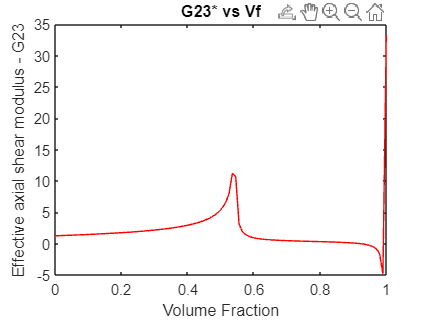

title("G23* vs Vf")
xlabel("Volume Fraction")
ylabel("Effective axial shear modulus - G23")